# **Лабораторная работа №2**

# **Дискретное преобразование Фурье.**

# **Амплитудный и фазовый спектры сигналов**

**Выполнил: Голев Андрей Дмитриевич, ИВТ-32.**

**Преподаватель: Лавриненко Александр Дмитриевич.**

## Задача №1

Требуется сформировать два синусоидальных сигнала с частотами $f_{01} =6\;\textrm{Гц}$ и $f_{02} =14\;\textrm{Гц}$ и начальными фазами $\varphi_{01} =\frac{3\cdot \pi \;}{4\;}\approx 2,3562$ и $\varphi_{02} =\frac{2\cdot \pi \;}{6\;}\approx 1,0472$. При этом длительность сигналов $T$ должна составлять $1\;с$, а частота дискретизации $f_s =64\;\textrm{Гц}$.

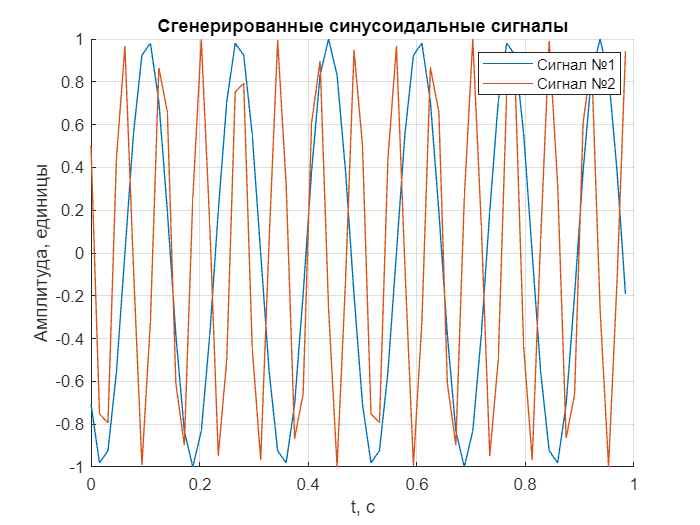

clc; clear; close all;
% Вариант №6, компьютер №14

f_01 = 6;
phase_01 = 3 * pi / 4;

f_02 = 14;
phase_02 = 2 * pi / 6;

f_s = 64;

t = ( 0 : 63 ) / f_s;

sig_1 = cos( 2 * pi * f_01 * t + phase_01 );
sig_2 = cos( 2 * pi * f_02 * t + phase_02 );

figure, hold on

plot( t, sig_1 )
plot( t, sig_2 )

title( "Сгенерированные синусоидальные сигналы" )
xlabel( "t, c" )
ylabel( "Амплитуда, единицы" )

legend( "Сигнал №1", "Сигнал №2" )

grid on

Смешаем сгенерированные сигналы:

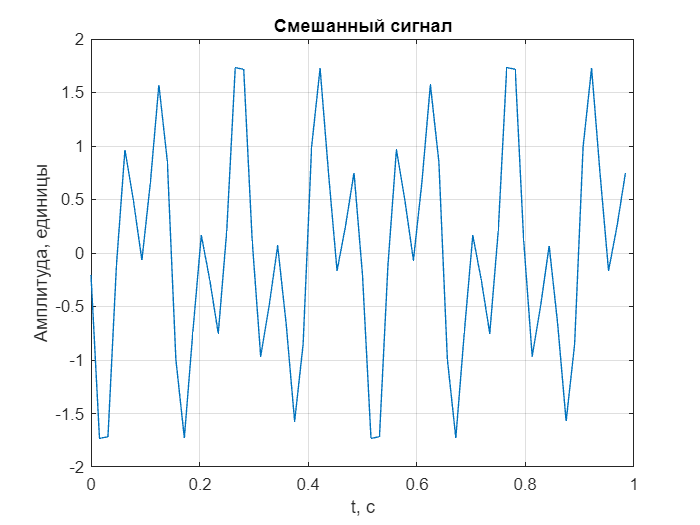

sig_sum = sig_1 + sig_2;

figure

plot( t, sig_sum )

title( "Смешанный сигнал" )
xlabel( "t, c" )
ylabel( "Амплитуда, единицы" )

grid on

Вычислим дискретное преобразование Фурье для смеси сигналов с помощью функции **fft( f, fftk )**, где

- **f** - сигнал, подвергаемый преобразованию Фурье,

- **fftk** - количество точек в ДПФ, равное количеству точек входного сигнала.

Это необходимо для того, чтобы перевести сигнал из временной области в частотную.

Fourier_sum = fft( sig_sum, length( sig_sum ) );

В итоге получили вектор комплексных отчётов спектра.

Построим амплитудный спектр. Чтобы это сделать, необходимо взять модули комплексных чисел, делённых на количество точек. Поскольку частота дискретизации сама по себе равна количеству отсчётов за период, то высокочастотные составляющие не могут быть корректно отображены из-за эффекта Маура. Это приводит к тому, что вторая половина комплексных амплитуд является зеркальным отображением первой и не несёт дополнительной информации.

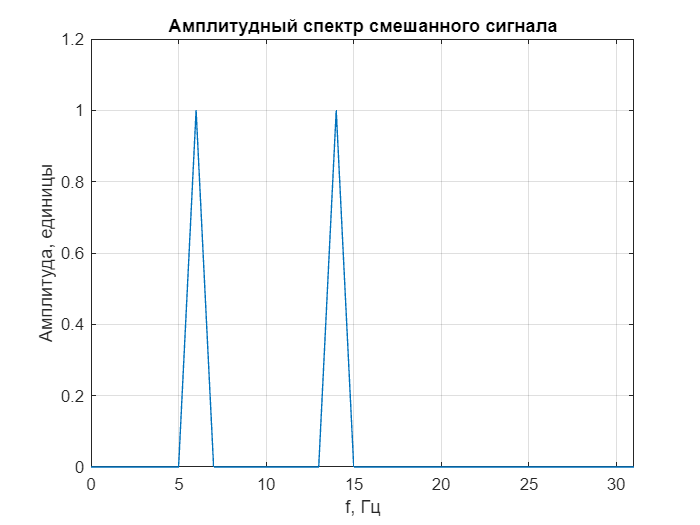

Amplitude_spectrum = 2 * abs( Fourier_sum / length( sig_sum ) )  ;

f = linspace( 0, f_s - 1, f_s );

figure

plot( f, Amplitude_spectrum )
xlim( [ 0, f_s / 2 - 1 ] )

title( "Амплитудный спектр смешанного сигнала" )
xlabel( "f, Гц" )
ylabel( "Амплитуда, единицы" )

grid on

Построим фазовый спектр сигнала, для чего необходимо взять аргументы комплексных чисел.

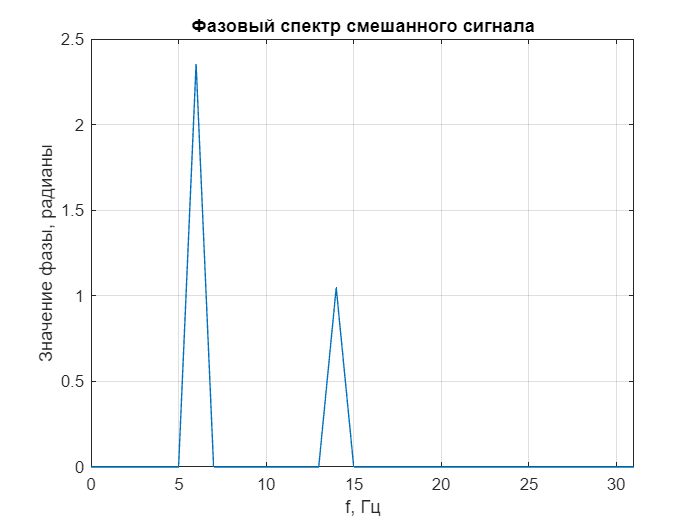

Fourier_sum ( abs( Fourier_sum ) < 1e-6 ) = 0;
Phase_spectrum = angle( Fourier_sum );

figure

plot( f, Phase_spectrum )
xlim( [ 0, f_s / 2 - 1 ] )

title( "Фазовый спектр смешанного сигнала" )
xlabel( "f, Гц" )
ylabel( "Значение фазы, радианы" )

grid on

Внесём в сумму сигналов шум удвоенной амплитуды сигналов

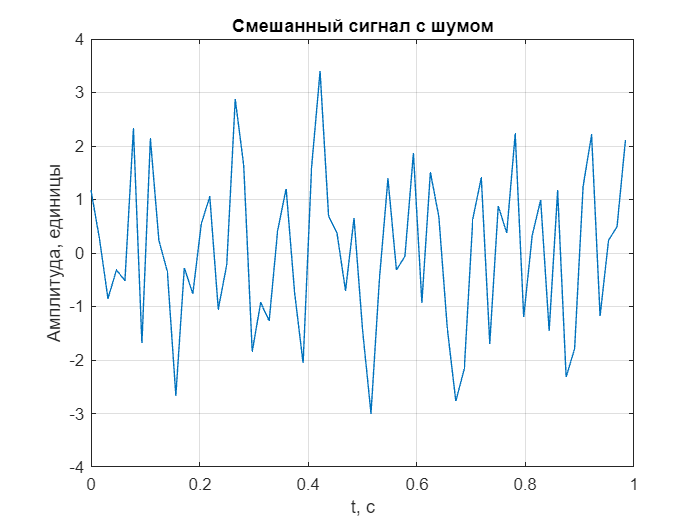

A_noise = 2;

Noise = A_noise - 2 * A_noise * rand( 1, f_s );

sig_noise = sig_sum + Noise;

figure

plot( t, sig_noise )

title( "Смешанный сигнал с шумом" )
xlabel( "t, c" )
ylabel( "Амплитуда, единицы" )

grid on

Рассчитаем спектры:

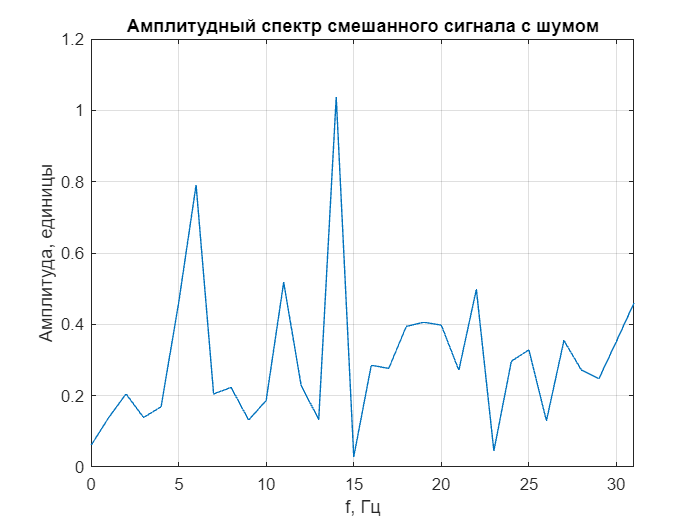

Fourier_noise = fft( sig_noise, length( sig_noise ) );

Amplitude_spectrum = 2 * abs( Fourier_noise ) / length( sig_noise )  ;

f = linspace( 0, f_s - 1, f_s );

figure

plot( f, Amplitude_spectrum )
xlim( [ 0, f_s / 2 - 1 ] )

title( "Амплитудный спектр смешанного сигнала с шумом" )
xlabel( "f, Гц" )
ylabel( "Амплитуда, единицы" )

grid on

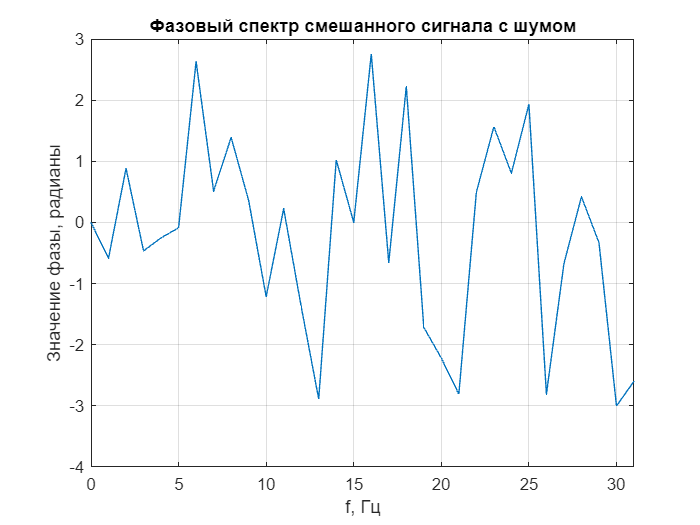


Fourier_noise ( abs( Fourier_noise ) < 1 ) = 0;
Phase_spectrum = angle( Fourier_noise );

figure

plot( f, Phase_spectrum )
xlim( [ 0, f_s / 2 - 1 ] )

title( "Фазовый спектр смешанного сигнала с шумом" )
xlabel( "f, Гц" )
ylabel( "Значение фазы, радианы" )

grid on